clc; clear; close all;

# 1D-FC with Gram Inteprolation

Precomputing matrices at high precision for interpolation

# Error Analysis

Doing steps above on sin(pix), will assume computation matrices aren't needed, i.e. they're already given in the FC_data folder.

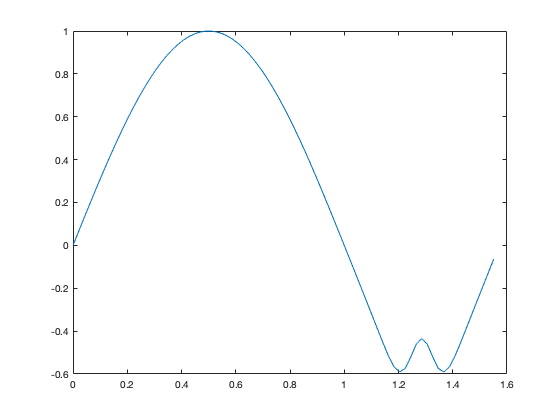

% fixed parameters
n_lst = [50, 100, 200];
d_lst = 3:8;
f = @(y) sin(pi*y);
C = 27;

err = zeros(length(d_lst), length(n_lst));

for i = 1%:length(d_lst)
    d = d_lst(i);

    load(['FC_data/A_d',num2str(d),'_C', num2str(C), '.mat']);
    load(['FC_data/Q_d',num2str(d),'_C', num2str(C), '.mat']);
    A = double(A);
    Q = double(Q);

    for j = 1%:length(n_lst)
        n = n_lst(j);
        h = 1/(n-1);
        
        x = transpose(linspace(0, 1, n));
        prd = (n+C)*h;
        [fx_cont_coeffs, fcont, ~, ~] = fcont_gram_blend(f(x), d, C, A, Q, Q);

        figure;
        plot(transpose(0:h:1+C*h), fcont)

        n_cont = n + C;
        shift_vector = exp(-1i*2*pi*(floor(n_cont/2))*transpose(0:(n_cont-1))/n_cont);

        fx_cont_coeffs = fftshift(fx_cont_coeffs);
        err(i, j) = max(abs(n_cont*ifft(fx_cont_coeffs).*shift_vector - fcont), [], 'all');
    end
end

err

err = 	1.0e+-13 *

    0.2193         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


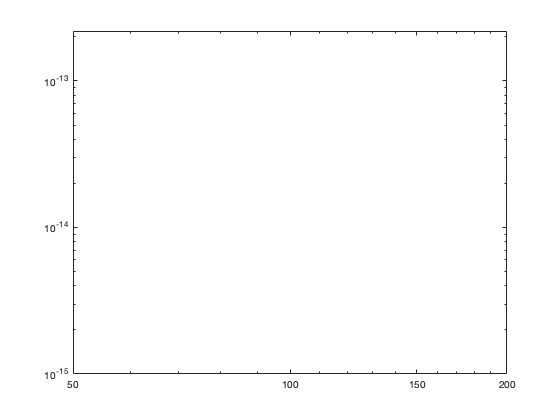

figure;
loglog(n_lst, err);


log2(err(:, 1:end-1) ./err(:, 2:end))

ans =    Inf   NaN
   NaN   NaN
   NaN   NaN
   NaN   NaN
   NaN   NaN
   NaN   NaN


% function f_y = f(r)
%     f_y = zeros(size(r));
%     f_y(r > 0.44) = exp(-1./(9*(r(r>0.44)-0.44).^2));
%     f_y(r <= 0.44) = 0;
% end